# Señales y Sistemas

Dedicamos un rato al principio de la clase para familiarizarnos con algunos términos que usaremos a lo largo del semestre

-Señal: es una función que describe una onda formada por muestras (Fenómenos que cambian en el tiempo)

-Sistema: cualquier proceso que modifique una señal

-Filtro: sistema que extrae las características de una señal

Vimos algunos ejemplos y hablamos un rato sobre las escalas que se manejan en algunos gremios (astrofísica y sismología operan con números muuuy diferentes)

## Señales contínuas y discretas

syms t

%Variable simbólica
y_symb=cos(t)

$$y\_symb = \cos\left(t\right)$$


%Function Handle
y_fh= @(t) cos(t)

y_fh = function_handle with value:
    @(t)cos(t)


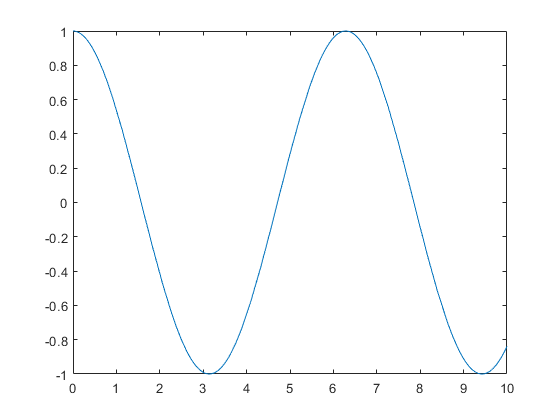



%fplot es para funciones simbólicas & "function handles"
figure
fplot(y_symb,[0,10])


figure
fplot(y_fh,[0,10])

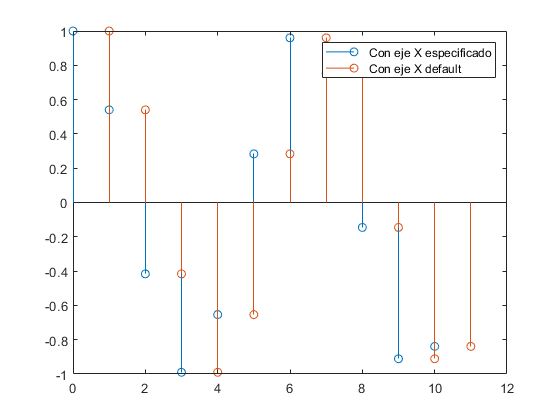


%y_fh([2 8 10]) se evalúa directo
%y_symb([2 8 10]) arroja error.
%La ventaja de la simbólica es que me permíte hacer álgebra
%matlabFunction convierte simbólica en handle

t_disc=0:10;
y_disc=y_fh(t_disc);

%plot(y_disc) nos da una gráfica fea
%usamos stem para observar lo que sí queremos
stem(t_disc,y_disc)
hold on
stem(y_disc)
legend('Con eje X especificado', 'Con eje X default')
hold off

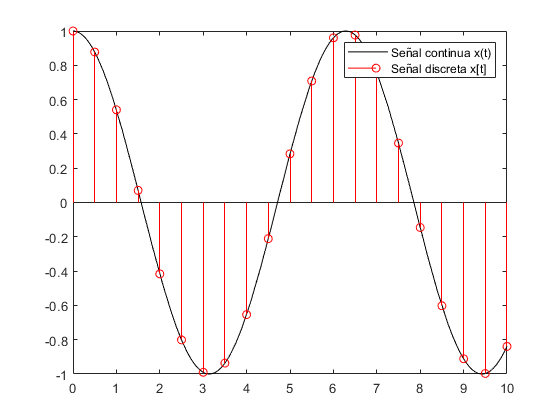

%ojo: stem(muestra) tiene el eje X cómo número de muesta a no ser que especifiques contra
%qué juega

t_disc=0:0.5:10;
y_disc=y_fh(t_disc);

fplot(y_fh,[0 10],'k')
hold on
stem(t_disc,y_disc,'r')
hold off
legend("Señal continua x(t)","Señal discreta x[t]")

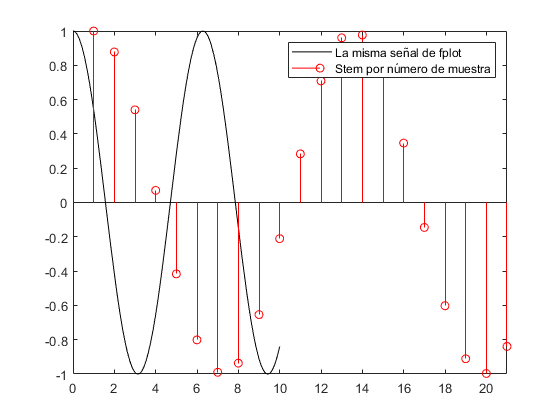

%Si no especificamos el tiempo como eje X en stem ocurre esto:

fplot(y_fh,[0 10],'k')
hold on
stem(y_disc,'r')
hold off
legend("La misma señal de fplot","Stem por número de muestra") %Puedes ver que hasta empieza en 1

## Formas de Onda básicas

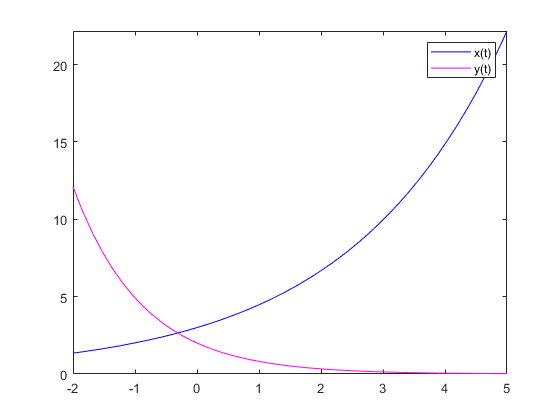

syms t

x_t=3*exp(0.4*t);

y_t=2*exp(-0.9*t);

%E1
fplot(x_t,[-2,5],'b')
hold on
fplot(y_t,[-2,5],'m')
legend('x(t)', 'y(t)')
hold off

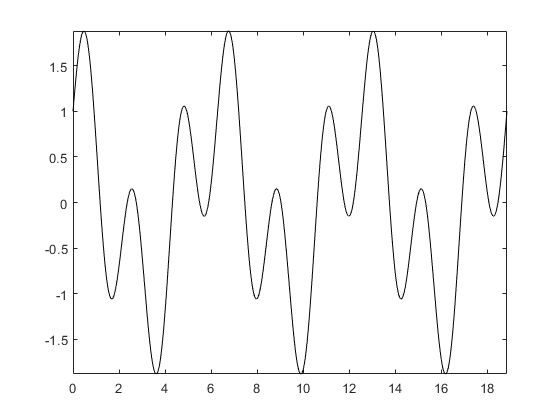


%E2
%Podemos usar sliders para ser fancy
G =1;
H = 1;
A=cos(G*t)+sin(H*3*t);
fplot(A,[0,6*pi],'k')

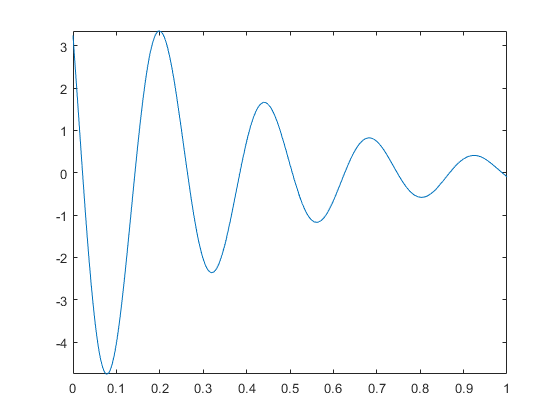


%DECAIMIENTO

C=  6;
r=-2.9;
W=  26 ;
TH= 1;


S(t)=C*exp(r*t)*cos(W*t + TH);

fplot(S,[0,1])

## Gráfica de la función Seno

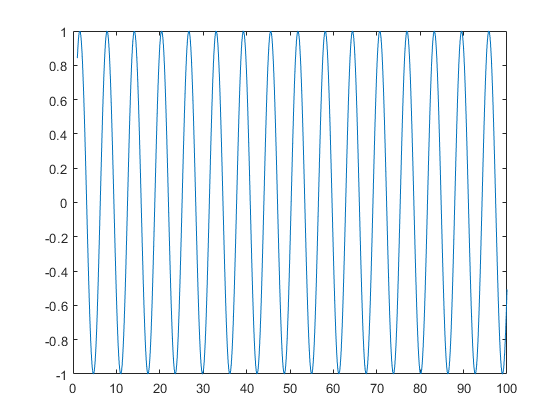

t= 1:0.1:100;
x_t= sin(t);

plot(t,x_t)

## Función Coseno

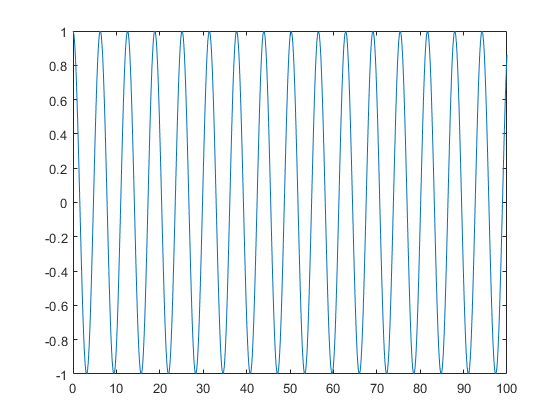

t=0:0.1:100;
C_t=cos(t);

plot(t,C_t)